# Filters artefacts

Current implementation expects "gapfinder" to be executed before.

TODO: Find the correct parameters again

Challenges of this method:

- Runtime

- Indepenance of the Gapfinder module (this used to be all in one file)

Parameters:

disp(filename); % parameters set probably depend on individual scan

09052017034420__ascan_2.bin


medfilt2_iteration_Th = 4; % amount of times medfilt2 should be executed
im2bw_Th_1 = 0.53; % threshhold for first im2bw
gaussfilt_Th = 6; % amount of times to execute gaussian filter
im2bw_Th_2 = 0.47; % threshhold for second im2bw

Get the original image to make sure we are not working ontop of modifications from "gapfinder".

C = original;

Increase contrast

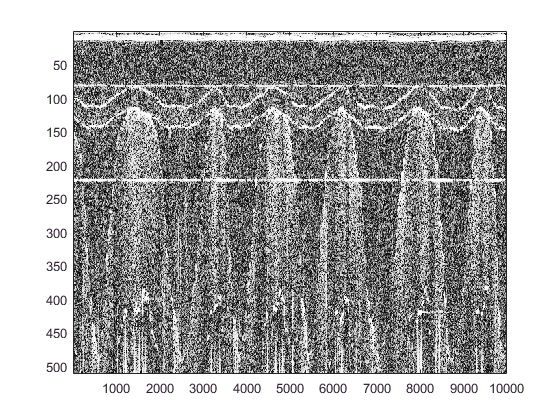

C = histeq(C); %possible alternative: imadjust(), gives worse results though
colormap gray;
imagesc(C);

Smooth it out

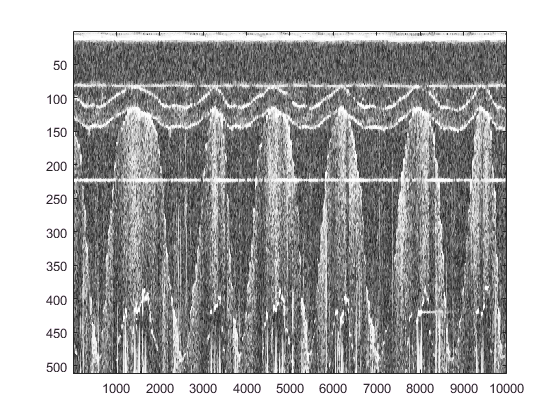

for i = 1:medfilt2_iteration_Th
    C = medfilt2(C,[3,3]);
end
imagesc(C)

Run Binaryze on it.

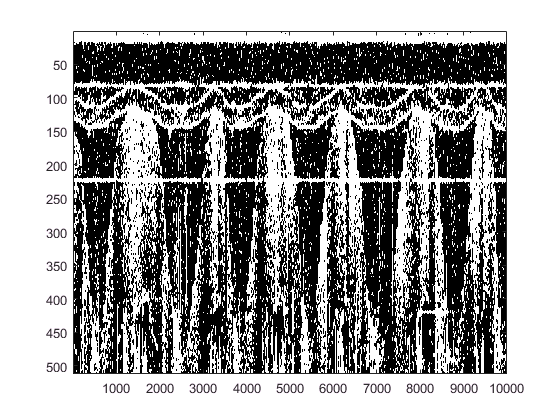

BW = im2bw(C, im2bw_Th_1);
imagesc(BW);

Try different filters for getting rid of noise.

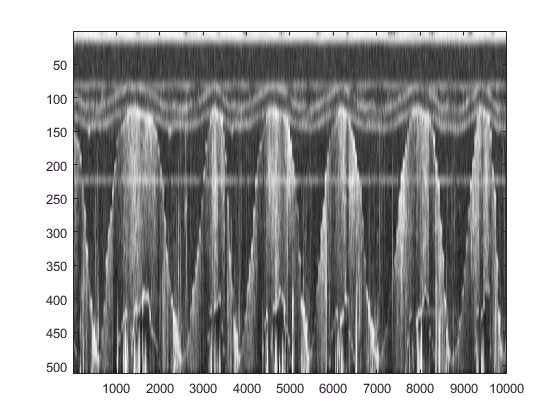

D_fixed=im2double(C);
Z = imgaussfilt(D_fixed, gaussfilt_Th);
imagesc(Z)

Run Binaryze on it (again).

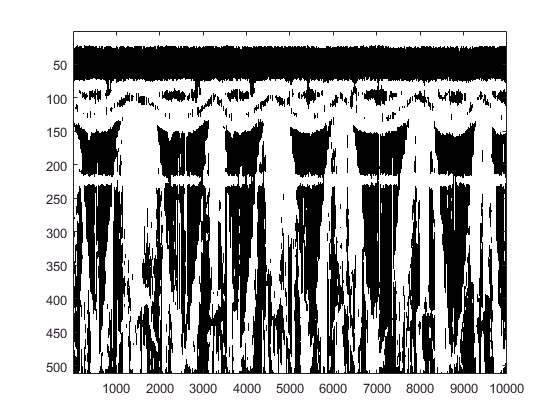

d_BW = im2bw(Z, im2bw_Th_2); % the higher the value the blacker the picture
figure; % attempt to make imagesc actually display something
colormap gray;
imagesc(d_BW);

Filtering the Artefact Line between Row 250 and 190 (expects Gapfinder to be executed before)

Artefact1 = im2double(d_BW);
Artefact_mask = zeros(size(Artefact1));
myfinish=2000; %finish-10;
for i = myfinish : -1 : 1 
    for j =  250 :-1: 190
        % überprüfe die beiden Punkte darunter auf weiß und einen Punkt 10 weiter rechts von dem schwarzen Punkt ausgehend
        if((Artefact1(j,i)==0) && (Artefact1(j + 1,i) == 1) && (Artefact1(j + 2,i) == 1) && (Artefact1(j+2,i+10) == 1)) 
            Artefact1(j,i) = 1;
            Artefact_mask(j,i) = 1;
        end
    end
    if (round(3*myfinish/4) == i) 
        disp('25% erreicht') 
    end
    if (round(myfinish/2) == i) 
        disp('50% erreicht') 
    end
    if (round(myfinish/4) == i) 
        disp('75% erreicht') 
    end
    if (2 == i) 
        disp('100% erreicht') 
    end
end

25% erreicht


imagesc(Artefact_mask);

Filtering Peaks and Lows (doesnt work well yet)

% Artefact2_finish = finish-10; %um den ganzen Bereich zu scannen
% for i = 11 : Artefact2_finish
%     for j =  170:300
%         if((Artefact_mask(j,i)==0) && ((Artefact1(j,i+10) == 1) && Artefact1(j,i-10) == 1)) 
%             Artefact_mask(j,i) = 1;
%         end
%     end
%     if (round(Artefact2_finish/4) == i) 
%         disp("25% erreicht") 
%     end
%     if (round(Artefact2_finish/2) == i) 
%         disp("50% erreicht") 
%     end
%     if (round(3*Artefact2_finish/4) == i) 
%         disp("75% erreicht") 
%     end
% end
% disp("100% erreicht")

Show previously computed mask

grey_val = 0.4; % todo manueller wert
for j = 250 : 1 : 190
    for i = 1 : 1 : myfinish
        if (Artefact_mask(j,i) == 1)
            original(j,i) = grey_val;
        end
    end
end
colormap gray;
imagesc(original);